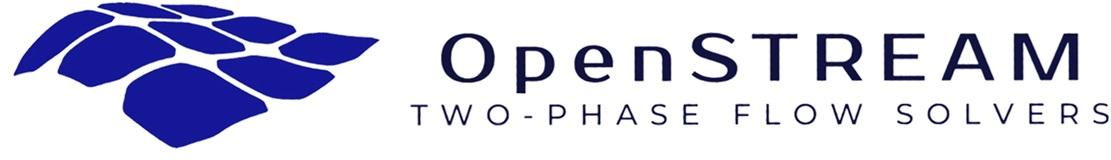

# Analysis of Bennett (1967) post-CHF data

## Introduction

In this project, post-critical heat flux (post-CHF) data are extracted from the following reference and analyzed using OpenSTREAM:

A. W. Bennett, G. F. Hewitt, H. A. Kersey and R. K. F. Keeys, Heat Transfer to Steam-Water Mixtures Flowing in Uniformly Heated Tubes in which the Critical Heat Flux has been Exceeded, UKAEA report, AERE-R 5373, 1967.

Two different solvers are employed for different aspects of the analysis:

- The mixture solver with thermal non-equilibrium capabilities is used to simulate wall temperature profiles.

- The three-field solver is used for mechanistic prediction of the elevation at which critical heat flux (CHF) occurs.

These two aspects can be combined, once thermal non-equilibrium capabilities are implemented in the three-field solver.

Before proceeding, ensure that both OpenSTREAM and OpenSTREAM-database are included in your MATLAB search path.

If you are working directly from the OpenSTREAM-database project folder, you can add the required paths using the following commands:

% Add path to OpenSTREAM
osp = './../../openstream';
addpath(osp);

% Add path to OpenSTREAM-database
osdp = './..';
addpath(osdp);

First, the Bennett1967 dataset class is  imported and an instance of this class is created, containing all experimental data.

% Import the database class
import Bennett1967.*

% Create an object of this class, loading all data
alldata = Bennett1967();

The dataset class includes methods that loads the experimental data, setup all OpenSTREAM inputs, run the code and post-process the results.

## Predictions of wall temperature

In the post-CHF region, the two-phase flow exhibits thermal non-equilibrium, where the vapor phase is typically superheated while the liquid phase remains saturated or subcooled.

This behavior can be modeled in OpenSTREAM using the mixture solver in combination with a thermal non-equilibrium formulation based on the Homogeneous Relaxation Model (HRM).

### Code inputs

The following `testID`, corresponding to the Run No. in the data report, are selected.

If desired, several test IDs can be selected within a cell array.

% Selected TestID
TestID = {[5360 5361 5349 5364]};

For example,  `TestID 5360 5361 5349 5364` correspond to the data shown in Figure 4 of the report, where all boundary conditions are held constant except for the applied power.

The inputs to OpenSTREAM consists of boundary conditions, physical models and numerical options. In OpenSTREAM-database, the required input files are automatically generated by the dataset class.

By default, physical models are initialized with standard settings, but here they are slightly adjusted to handle test cases involving thermal non-equilibrium conditions.

Specifically:

- Fluid properties are computed based on system pressure and phase enthalpy.

- The thermal non-equilibrium model is set to the Homogeneous Relaxation Model (HRM).

- A multiplier on Biasi Critical Boiling Transition (CBT) model is applied, based on good agreement with the experimental data.

% Initialize input options structure
opts = alldata.inputOptions();

opts.model.ID           = 'POSTDO';                                % Model ID
opts.model.PROPERTIES   = 'PSYSTEM';                               % Fluid properties model
opts.model.THERMALNONEQ = 'RELAXATION';                            % Thermal non-equilibrium model

% Thermal non-equilibrium models
opts.model.THERMALRELAX = 'QUALITY';                               % Quality-dependent model
opts.model.RELAXX       = [-0.5 -0.25 -0.1 0.0 1.0];               % Interfacial phase change relaxation time thermodynamic quality [-]
opts.model.RELAXTCOND   = [ 1.0  0.5   0.3 0.1 0.1];               % Interfacial condensation relaxation time array [s]
opts.model.RELAXTEVAP   = [ 0.3  0.3   0.3 0.3 0.3];               % Interfacial evaporation  relaxation time array [s]

% Critical boiling transition models
opts.model.CBT          = 'BIASI';                                 % Biasi CBT model
opts.model.CBTMULT      = @(z) 0.6;                                % CBT multiplier

The numerical options in the codes are initialized with default values.

These can be adjusted as needed, for instance in case of solver convergence issues.

%opts.options.RELAXWV    = 0.8;
%opts.options.RELAXHV    = 0.8;

Additional solver options are defined below.

inputSetOpts = {'overwriteSessionFiles', true, 'LOGMODE', 'BOTH'};
saveResultsToFile = false;

Setting `LOGMODE` to `NONE` enables printing of the solver convergence log to the screen (and log file). This is convenient to monitor the convergence status of the code.

### Simulations

Before starting the simulations, the run indices in the dataset are identified based on the specified `TestID`.

Once identified, OpenSTREAM runs can  be executed using the mixture solver. This is done by invoking the methods to generate and write the specific input files for each run (`makeInputFiles`) and launch the solver (`runCase`). For improved performance, a parfor loop may be used instead of a standard for loop to enable parallel execution.

⚠️ Note : When performing parallel runs, the following warning may appear:

`Unable to load Python object. Saving (serializing) Python objects into a MAT-file is not supported.`

This is a known issue and does not affect the successful completion of the simulations.

Finally, you can verify the successful convergence of the runs using the `checkConvergence` method.

N = length(TestID);

% Loop over all TestID
clear test
for k = 1:N


    % Run indices
    runs = find(ismember(alldata.dataset.TestID,TestID{k}));

    clear data
    parfor i = 1:length(runs)
        %for i = 1:length(runs)

        % Read data and write OpenSTREAM input files
        data(i) = Bennett1967(runs(i));
        data(i).makeInputFiles(opts);

        % Run OpenSTREAM mixture
        warning('off','all')
        data(i).runCase('Mixture','inputSetOpts',inputSetOpts,'saveResultsToFile',saveResultsToFile);
        warning('on','all')

    end
    
    % Check convergence status
    data.checkConvergence();

    % Save in test structure
    test(k).data = data; 
end

For convenience, the output `data` for each run are saved into the `test` structure.

### Post-processing

Finally, the axial distributions of phase and wall temperature can be plotted alongside the corresponding measurement data.

Once the figure is generated, click the "Open in figure window" icon located at the top-right corner of the plot to better visualize the distributions.

arrayfun(@(x) x.data.plotResults('Mixture',{'temperature'},'Z','C'),test);

## Predictions of CHF elevation

In the annular flow region region, the two-phase flow is saturated up to complete liquid film dryout.

The dryout of the liquid film can be modeled in OpenSTREAM using the three-field solver with appropriate physical models.

### Code inputs

The selection of tests from the data report can be done by `TestName` (instead of `TestID`).

If desired, several test names can be selected within a cell array.

% Selected TestName
%TestName = {'219in - 0.3 [Mlb/ft^2/hr]'};
TestName = {'219in - 0.3 [Mlb/ft^2/hr]','219in - 0.5 [Mlb/ft^2/hr]','219in - 0.8 [Mlb/ft^2/hr]','219in - 1.0 [Mlb/ft^2/hr]','219in - 1.4 [Mlb/ft^2/hr]','219in - 1.9 [Mlb/ft^2/hr]','219in - 2.8 [Mlb/ft^2/hr]','219in - 3.8 [Mlb/ft^2/hr]'};
%TestName = {'144in - 0.5 [Mlb/ft^2/hr]','144in - 1.0 [Mlb/ft^2/hr]','144in - 1.4 [Mlb/ft^2/hr]','144in - 1.9 [Mlb/ft^2/hr]','144in - 2.9 [Mlb/ft^2/hr]','144in - 3.5 [Mlb/ft^2/hr]'};

The physical models from the previous cases are slightly adjusted to run the three-field solver. Since this solver has (for now) no thermal non-equilibrium capabilities, it is sufficient to calculate all fluid properties at saturation and initialize the cases with the mixture model based on thermal equilibrium assumptions . While the liquid film model pertaining to the onset of annular flow, film entrainment and drop deposition are unchanged from their default values, they are specified here for clarity. Finally, the negative film flow rate capabilities of the code are turned on to easily detect where the complete film dryout is predicted.

opts.model.ID           = 'FILM';                              % Model ID
opts.model.PROPERTIES   = 'SATURATED';                         % Fluid properties
opts.model.THERMALNONEQ = 'EQUILIBRIUM';                       % Thermal non-equilibrium model

% Film models
opts.model.OAFENTRAINED = 'EQUILIBRIUM';                       % Entrained drop model at onset of annular flow
opts.model.DEPOSITION   = 'OKAWA';                             % Drop deposition model
opts.model.ENTRAINMENT  = 'OKAWA2003';                         % Film entrainment model
opts.model.POSFILM      = 0;                                   % Positive film flowrate/thickness model

The numerical options in the codes remain the same.

Additional solver options are defined below.

inputSetOpts = {'overwriteSessionFiles', true, 'LOGMODE', 'NONE'};

Setting `LOGMODE` to `NONE` disables printing of the solver convergence log to the screen. This is useful when a large number of runs is performed.

### Simulations

Before starting the simulations, the run indices in the dataset are identified based on the specified `TestName`.

Once identified, OpenSTREAM runs can  be executed using the three-field solver. This is done by invoking the methods to generate and write the specific input files for each run (`makeInputFiles`) and launch the solver (`runCase`). For improved performance, a parfor loop may be used instead of a standard for loop to enable parallel execution.

Finally, you can verify the successful convergence of the runs using the `checkConvergence` method.

N = length(TestName);

% Loop over all test names
clear test
for k = 1:N

    % Run indices
    fprintf('\nTest name = %s\n',TestName{k})
    runs = find(ismember(alldata.dataset.TestName',TestName{k}));

    clear data
    parfor i = 1:length(runs)
    %for i = 1:length(runs)

        % Read data and write OpenSTREAM input files
        data(i) = Bennett1967(runs(i));
        data(i).makeInputFiles(opts);

        % Run OpenSTREAM three-field
        warning('off','all')
        data(i).runCase('ThreeField','inputSetOpts',inputSetOpts,'saveResultsToFile',saveResultsToFile);
        warning('on','all')

    end

    % Check convergence status
    data.checkConvergence();

    % Save in test structure
    test(k).data = data;

end

For convenience, the output data for each run are saved into the test structure.

### Post-processing

The axial distributions of predicted film flow ate and measured wall temperature  are plotted.

In the provided example, the plots are generated only for the first `TestName`.

Once the figure is generated, click the "Open in figure window" icon located at the top-right corner of the plot to better visualize the distributions.

% Plot distributions of predicted film flow ate and measured wall temperature
test(1).data.plotResults('ThreeField',{'film','temperature'},'Z','C');
%arrayfun(@(x) x.data.plotResults('ThreeField',{'film','temperature'},'Z','C'),test);

Finally, the predicted elevations of film dryout are compared against the experimental measurements from all selected `TestNames`.

Once the figure is generated, click the "Open in figure window" icon located at the top-right corner of the plot to better visualize the distributions.

% Predicted and measured dryout elevations
arrayfun(@(x) x.data.plotResults('ThreeField',{'doelevation'},'Z','C',true),test);